# ISC recordings - tecta-cre;Cx26flfl with P2ry1 inhibition

% room temp, 6K ACSF
defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\Inner SCs 6K'

defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\Inner SCs 6K'

cd(defaultDir);


% Adjacent to IHCs
[tectaCx261 time1] = loadPclampData('2019_08_28_0013_adjusted.abf');

** abfload
opening 2019_08_28_0013_adjusted.abf..
data were acquired in gap-free mode


[tectaCx262 time2] = loadPclampData('2019_08_28_0010_adjusted.abf');

** abfload
opening 2019_08_28_0010_adjusted.abf..
data were acquired in gap-free mode


[tectaCx263 time3] = loadPclampData('2019_11_05_0001_baseline.abf');

** abfload
opening 2019_11_05_0001_baseline.abf..
data were acquired in gap-free mode


[tectaCx264 time4] = loadPclampData('2019_11_05_0006_baseline.abf');

** abfload
opening 2019_11_05_0006_baseline.abf..
data were acquired in gap-free mode


[tectaCx265 time5] = loadPclampData('2019_11_18_0004_adjusted.abf');

** abfload
opening 2019_11_18_0004_adjusted.abf..
data were acquired in gap-free mode


[tectaCx266 time6] = loadPclampData('2019_11_18_0008_adjusted2.abf');

** abfload
opening 2019_11_18_0008_adjusted2.abf..
data were acquired in gap-free mode


[tectaCx267 time7] = loadPclampData('2021_01_06_0015.abf');

** abfload
opening 2021_01_06_0015.abf..
data were acquired in gap-free mode


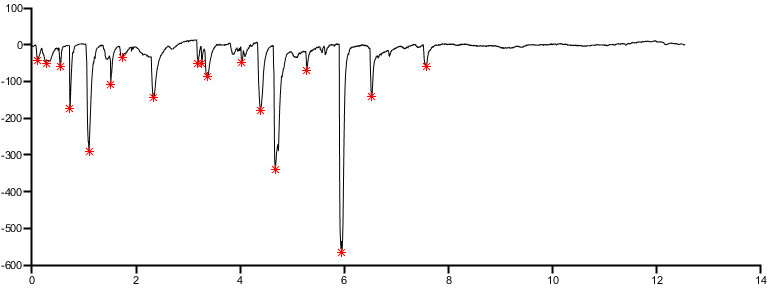

preFreq1 = 2

postFreq1 = 0

preAmp1 = -159.0563

postAmp1 = NaN

preCharge1 = 5.2755e-06

postCharge1 = 1.2103e-06

tectaCx267 = msbackadj(time7, -tectaCx267, 'WindowSize', 60,'StepSize',30);


% from prior exp - 2.5 k 
%[tectaCx263 time3] = loadPclampData('2018_11_06_0011_mrs2500.abf');


[preFreq1,postFreq1,preAmp1,postAmp1,preCharge1,postCharge1] = freqAmpISCbaseline2(tectaCx261,time1,8)

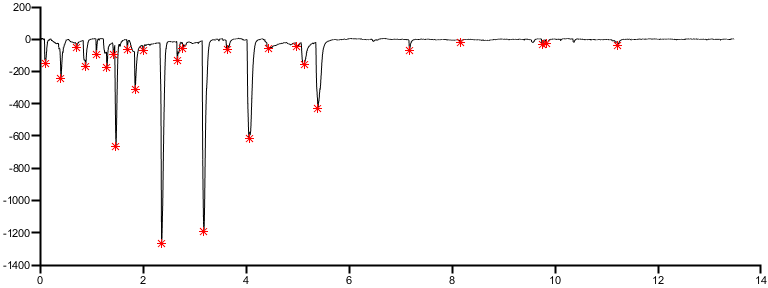

preFreq2 = 2.6000

postFreq2 = 1

preAmp2 = -343.4032

postAmp2 = -36.9206

preCharge2 = 2.7050e-06

postCharge2 = 1.7293e-06

[preFreq2,postFreq2,preAmp2,postAmp2,preCharge2,postCharge2] = freqAmpISCbaseline2(tectaCx262,time2,6.5)

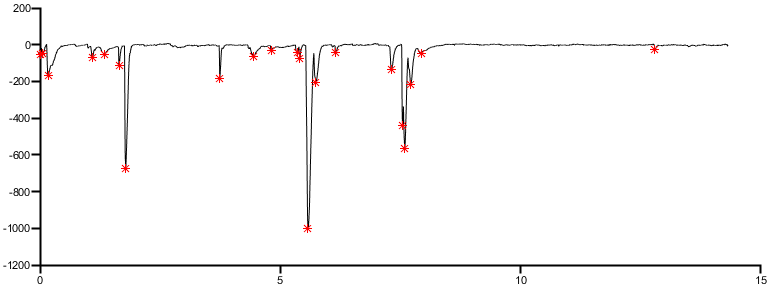

preFreq3 = 2.6000

postFreq3 = 0.2000

preAmp3 = -234.5014

postAmp3 = -26.2632

preCharge3 = 5.5770e-05

postCharge3 = 3.4493e-06

%[preFreq3,postFreq3,preAmp3,postAmp3,preCharge3,postCharge3] = freqAmpISCbaseline2(tectaCx263,time3,11.5)
[preFreq3,postFreq3,preAmp3,postAmp3,preCharge3,postCharge3] = freqAmpISCbaseline2(tectaCx263,time3,8)

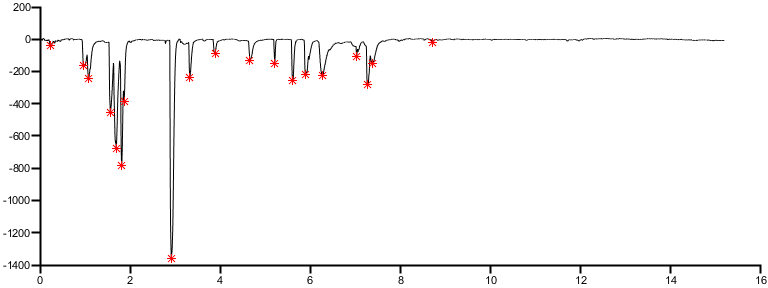

preFreq4 = 1.8000

postFreq4 = 0.2000

preAmp4 = -178.1506

postAmp4 = -21.5215

preCharge4 = 3.1345e-06

postCharge4 = 1.2822e-06

[preFreq4,postFreq4,preAmp4,postAmp4,preCharge4,postCharge4] = freqAmpISCbaseline2(tectaCx264,time4,8.5)

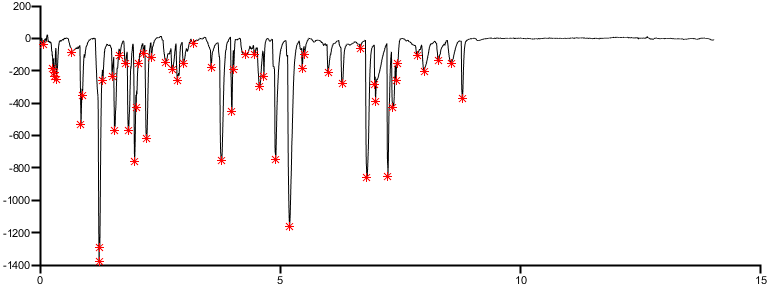

preFreq5 = 4.8000

postFreq5 = 0

preAmp5 = -327.4103

postAmp5 = NaN

preCharge5 = 4.7533e-05

postCharge5 = 1.1595e-06

[preFreq5,postFreq5,preAmp5,postAmp5,preCharge5,postCharge5] = freqAmpISCbaseline2(tectaCx265,time5,9)

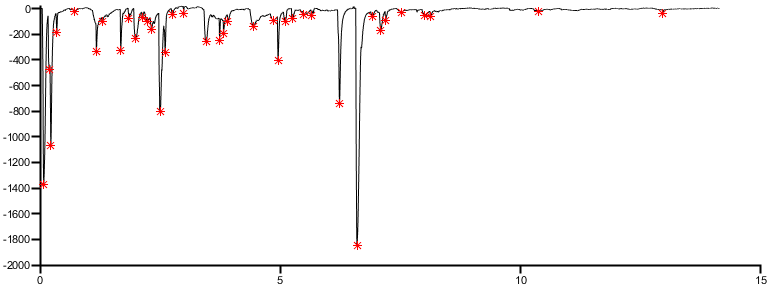

preFreq6 = 4

postFreq6 = 0.8000

preAmp6 = -291.0106

postAmp6 = -42.0100

preCharge6 = 1.1087e-04

postCharge6 = 1.2732e-05

[preFreq6,postFreq6,preAmp6,postAmp6,preCharge6,postCharge6] = freqAmpISCbaseline2(tectaCx266,time6,7.5)

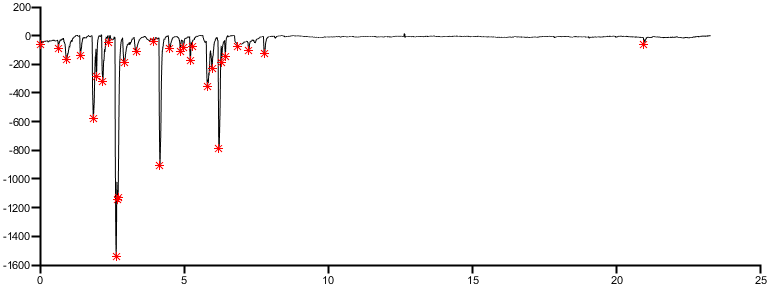

preFreq7 = 3.2000

postFreq7 = 0

preAmp7 = -225.3576

postAmp7 = NaN

preCharge7 = 2.4471e-05

postCharge7 = 2.4221e-06

[preFreq7,postFreq7,preAmp7,postAmp7,preCharge7,postCharge7] = freqAmpISCbaseline2(-tectaCx267,time7,8)



preF = [preFreq1,preFreq2,preFreq3,preFreq4,preFreq5,preFreq6,preFreq7];
postF = [postFreq1,postFreq2,postFreq3,postFreq4,postFreq5,postFreq6,postFreq7];
preA = abs([preAmp1,preAmp2,preAmp3,preAmp4,preAmp5,preAmp6,preAmp7]);
postA = abs([postAmp1,postAmp2,postAmp3,postAmp4,postAmp5,postAmp6,postAmp7]);
preC = [preCharge1,preCharge2,preCharge3,preCharge4];
postC = [postCharge1,postCharge2,postCharge3,postCharge4];


% plots
conditions = {'Baseline','+MRS2500'};
ylbl1 = 'Events per minute';
ylbl2 = 'Mean amplitude (-pA)';
ylbl3 = 'normalized charge (pA*S)';
dim = [1 2];
[fig1 p1] = compare2_2(preF,postF,conditions,ylbl1,dim);

not normal
    0.0156



yticks([0 2 4 6]);
 ylim([0 6]);


[fig2 p2] =compare2_2(preA,postA,conditions,ylbl2,dim);

    0.0054



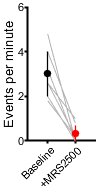

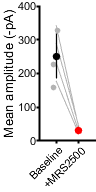


 ylim([0 400]);
 
% [hAmp pAmp] =compare2_2(preC,postC,conditions,ylbl3,dim);
% ylim([0 700]); 
 
subP = handleTheSubplot({fig1,fig2},[1 2]);

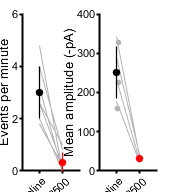

figQuality(subP,gca,[1.8 2])


[CorrP CorrA h] = fdr_BH([p1,p2],0.05)

CorrP =     0.0156    0.0108


CorrA =     0.0500    0.0250


h = 2×1 logical array
   1
   1


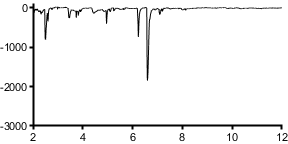

% pretty example plot

% tecta-cre; cx26 fl/fl close to IHC
figure;
%[tectaCx262 time2] = loadPclampData('2019_08_28_0010.abf');
tectacx = medfilt1(tectaCx266,100);
plot(time6()/60,tectacx(),'k','LineWidth', 1)
ylim([-3000 100]);
xlim([2 12])
figQuality(gcf,gca,[3 1.5])